## 1. Image Loading

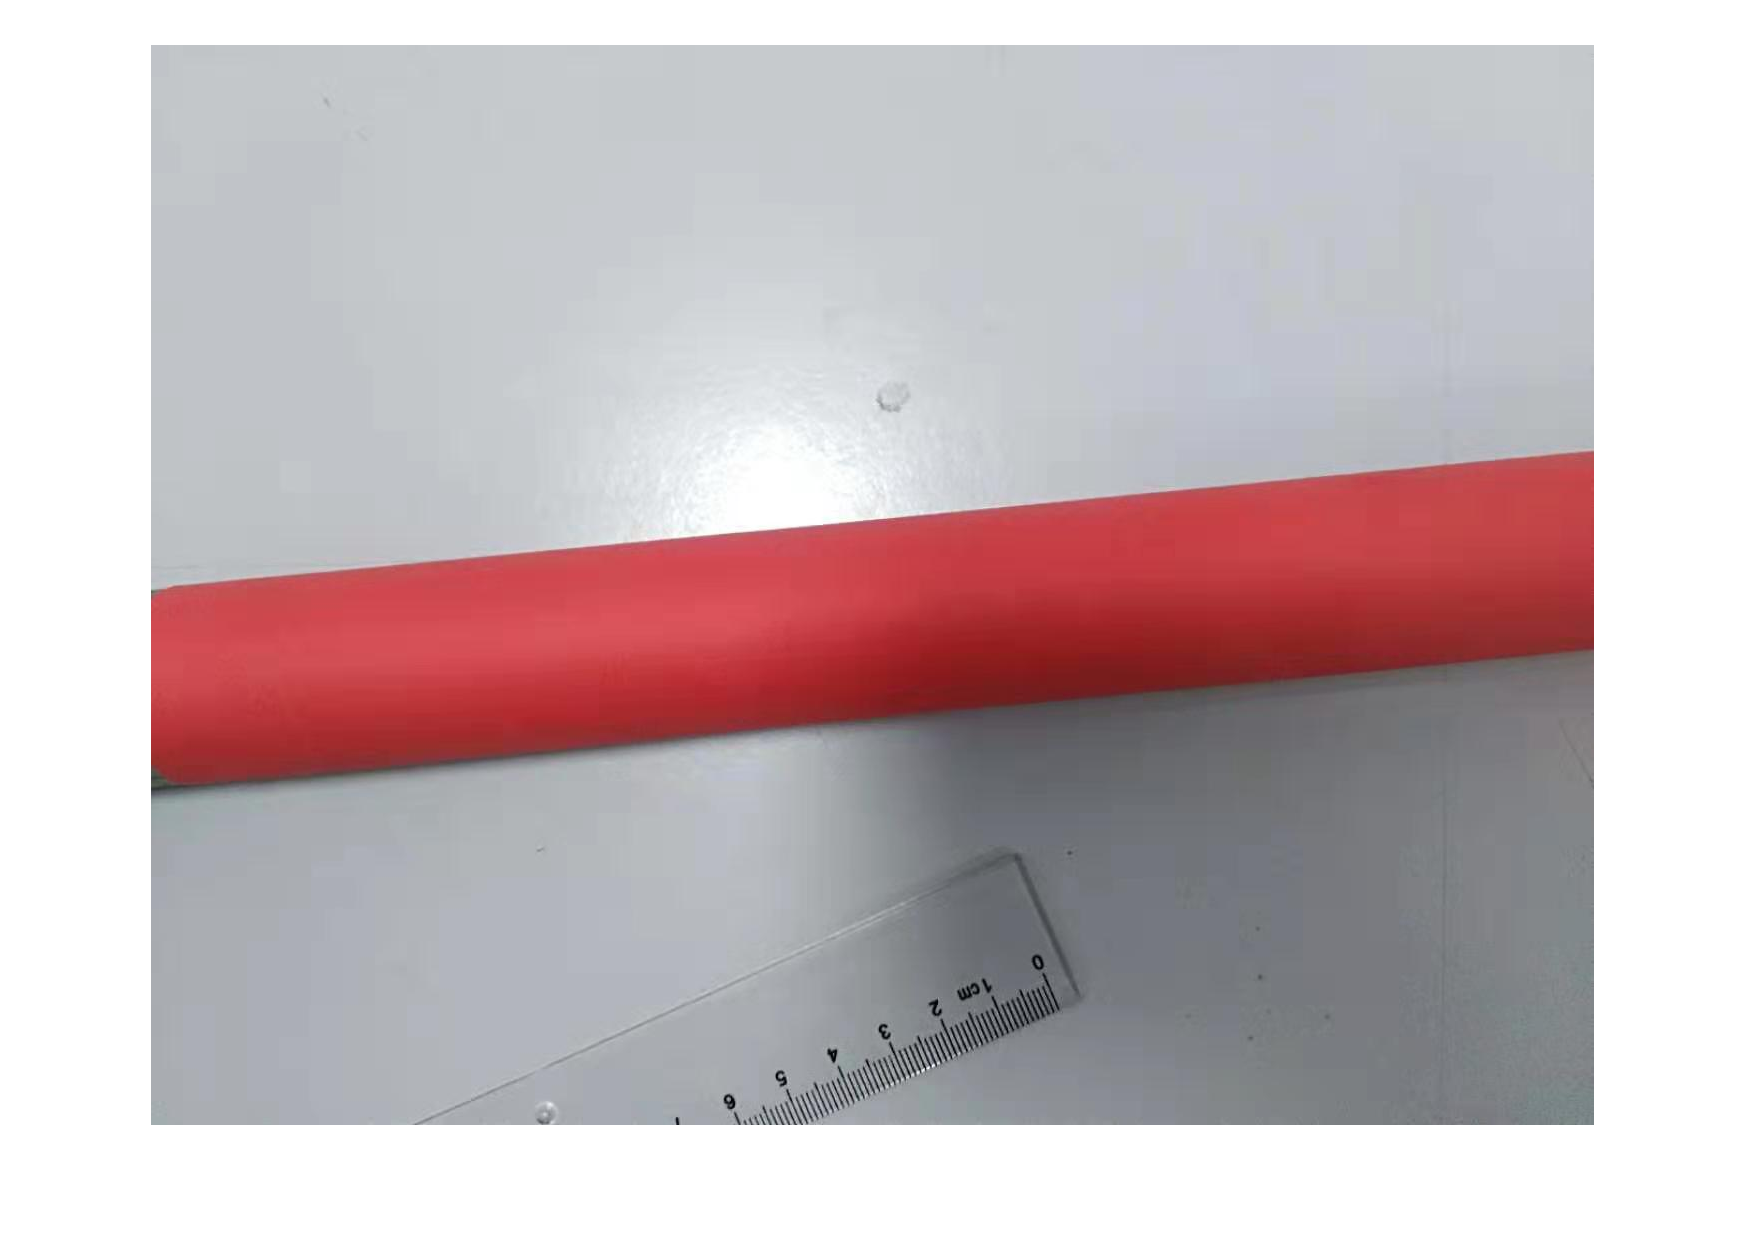

img = imread("./data/3.jpg");
img = im2double(img);
width=size(img,2);
height=size(img,1);
length = sqrt(width*height);

figure, imshow(img);

## 2. Hough Transform

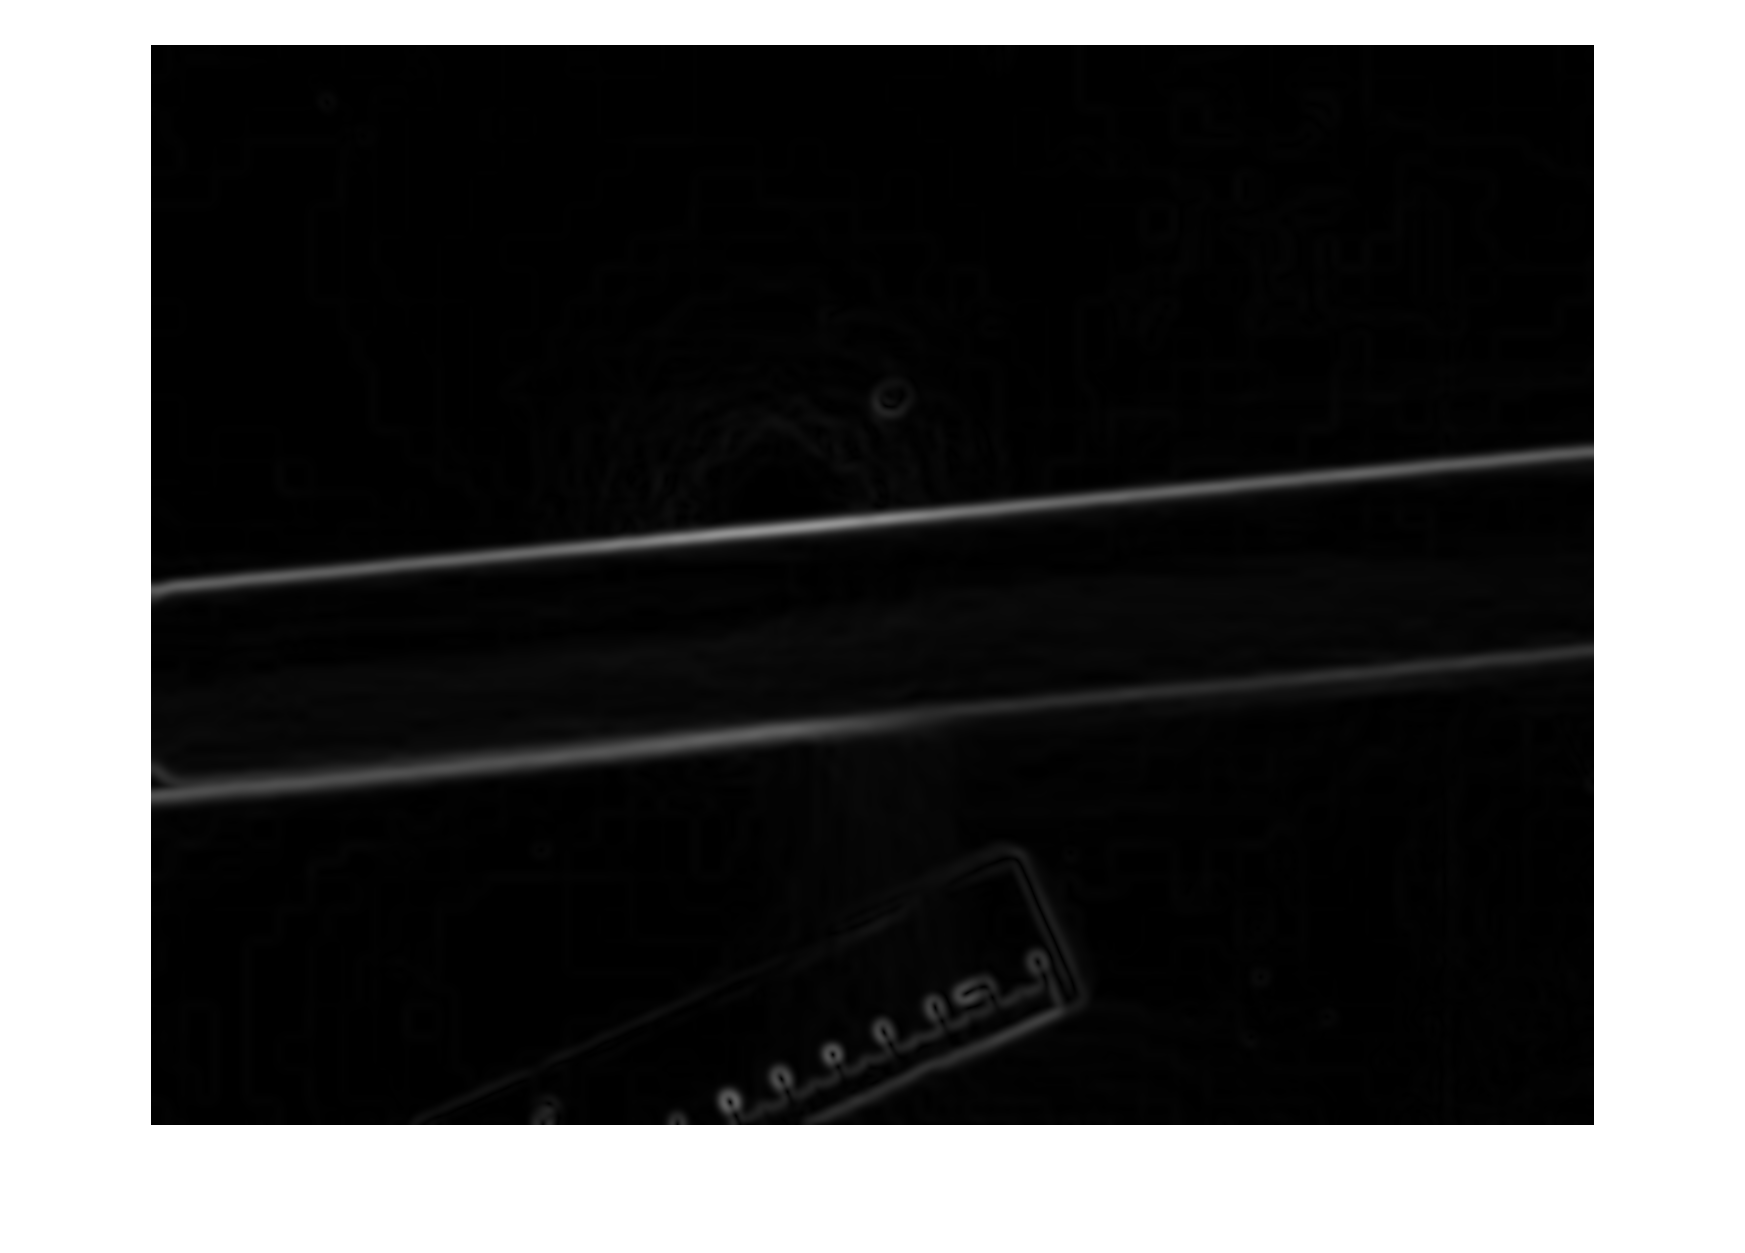

edges = compute_edges(img,5);

figure, imshow(edges);

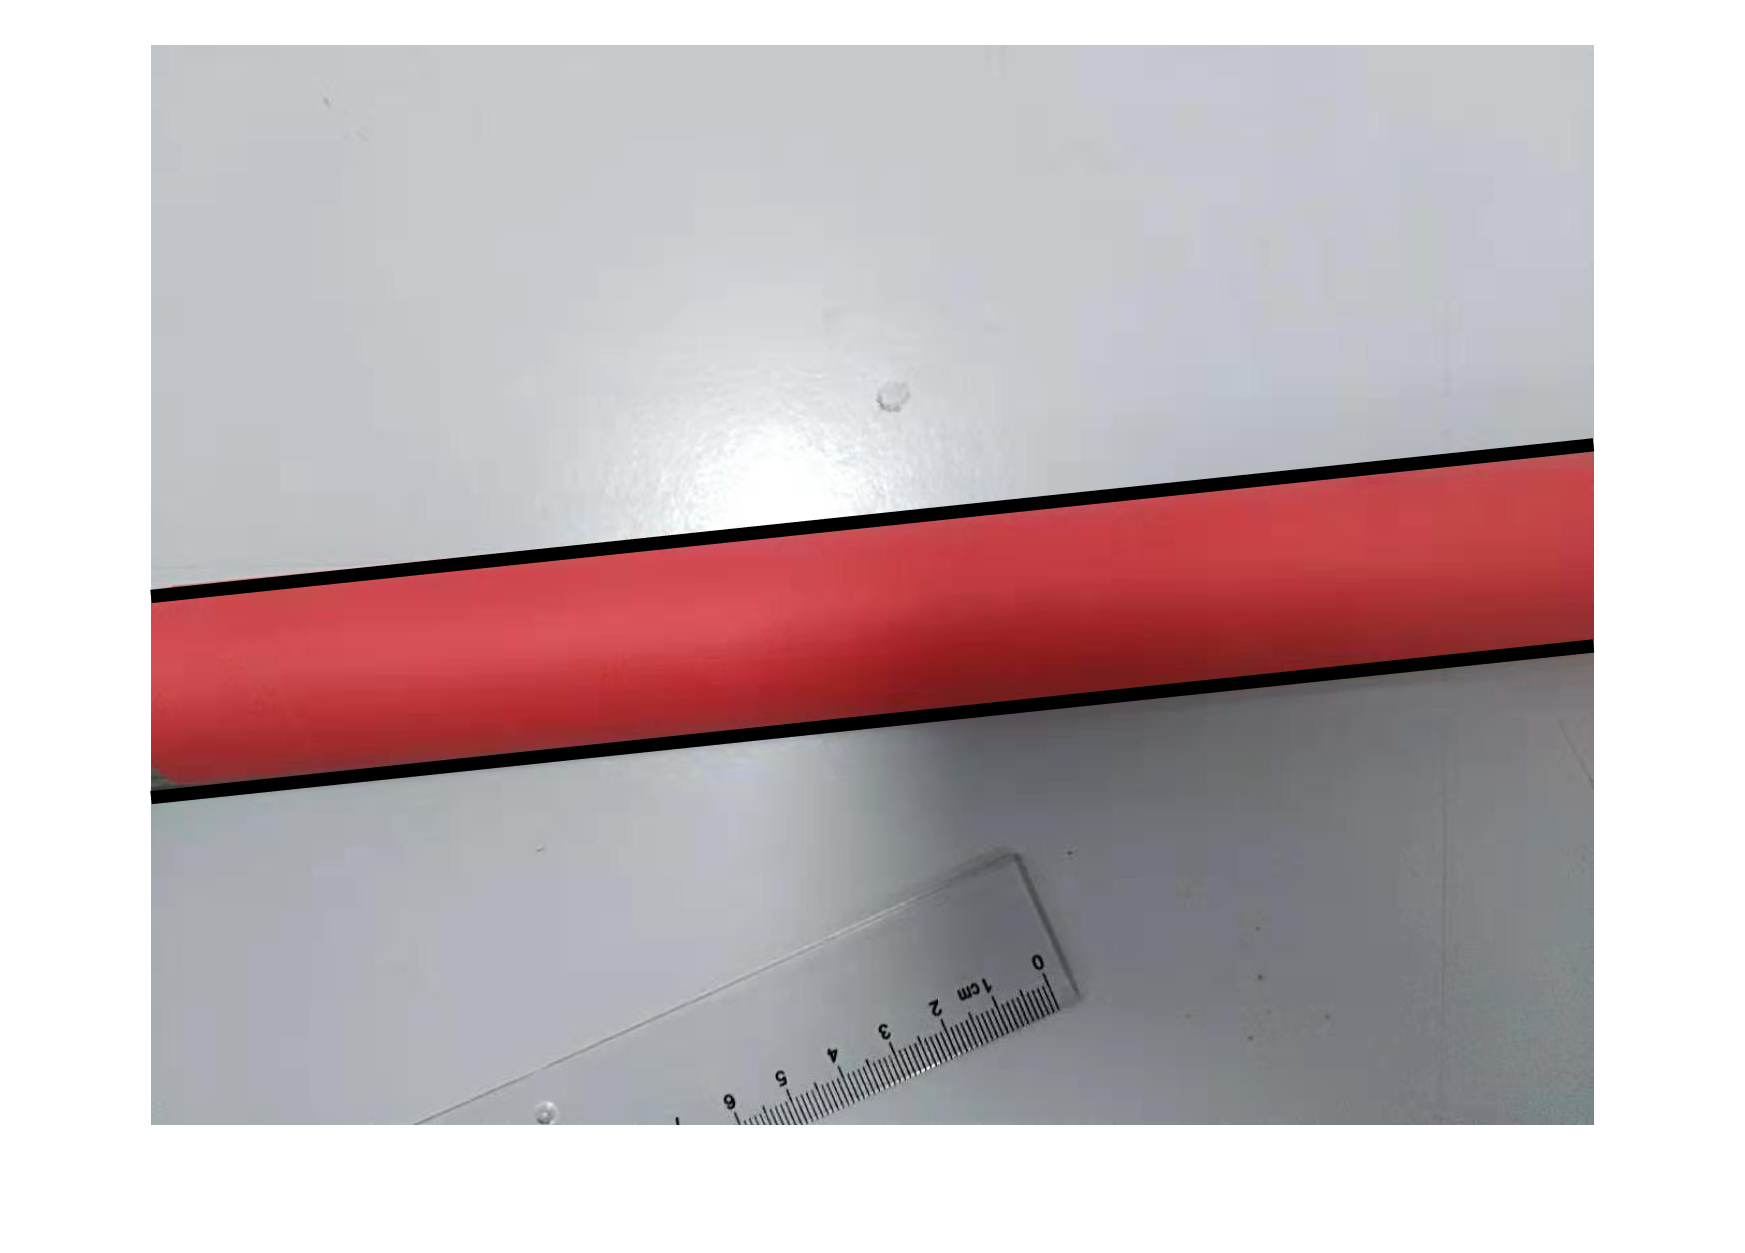

[theta1, rho1, theta2, rho2] = find_parallel(edges,0.03);

figure; imshow(img), hold on
plot_line(width,height,theta1,rho1);
plot_line(width,height,theta2,rho2);

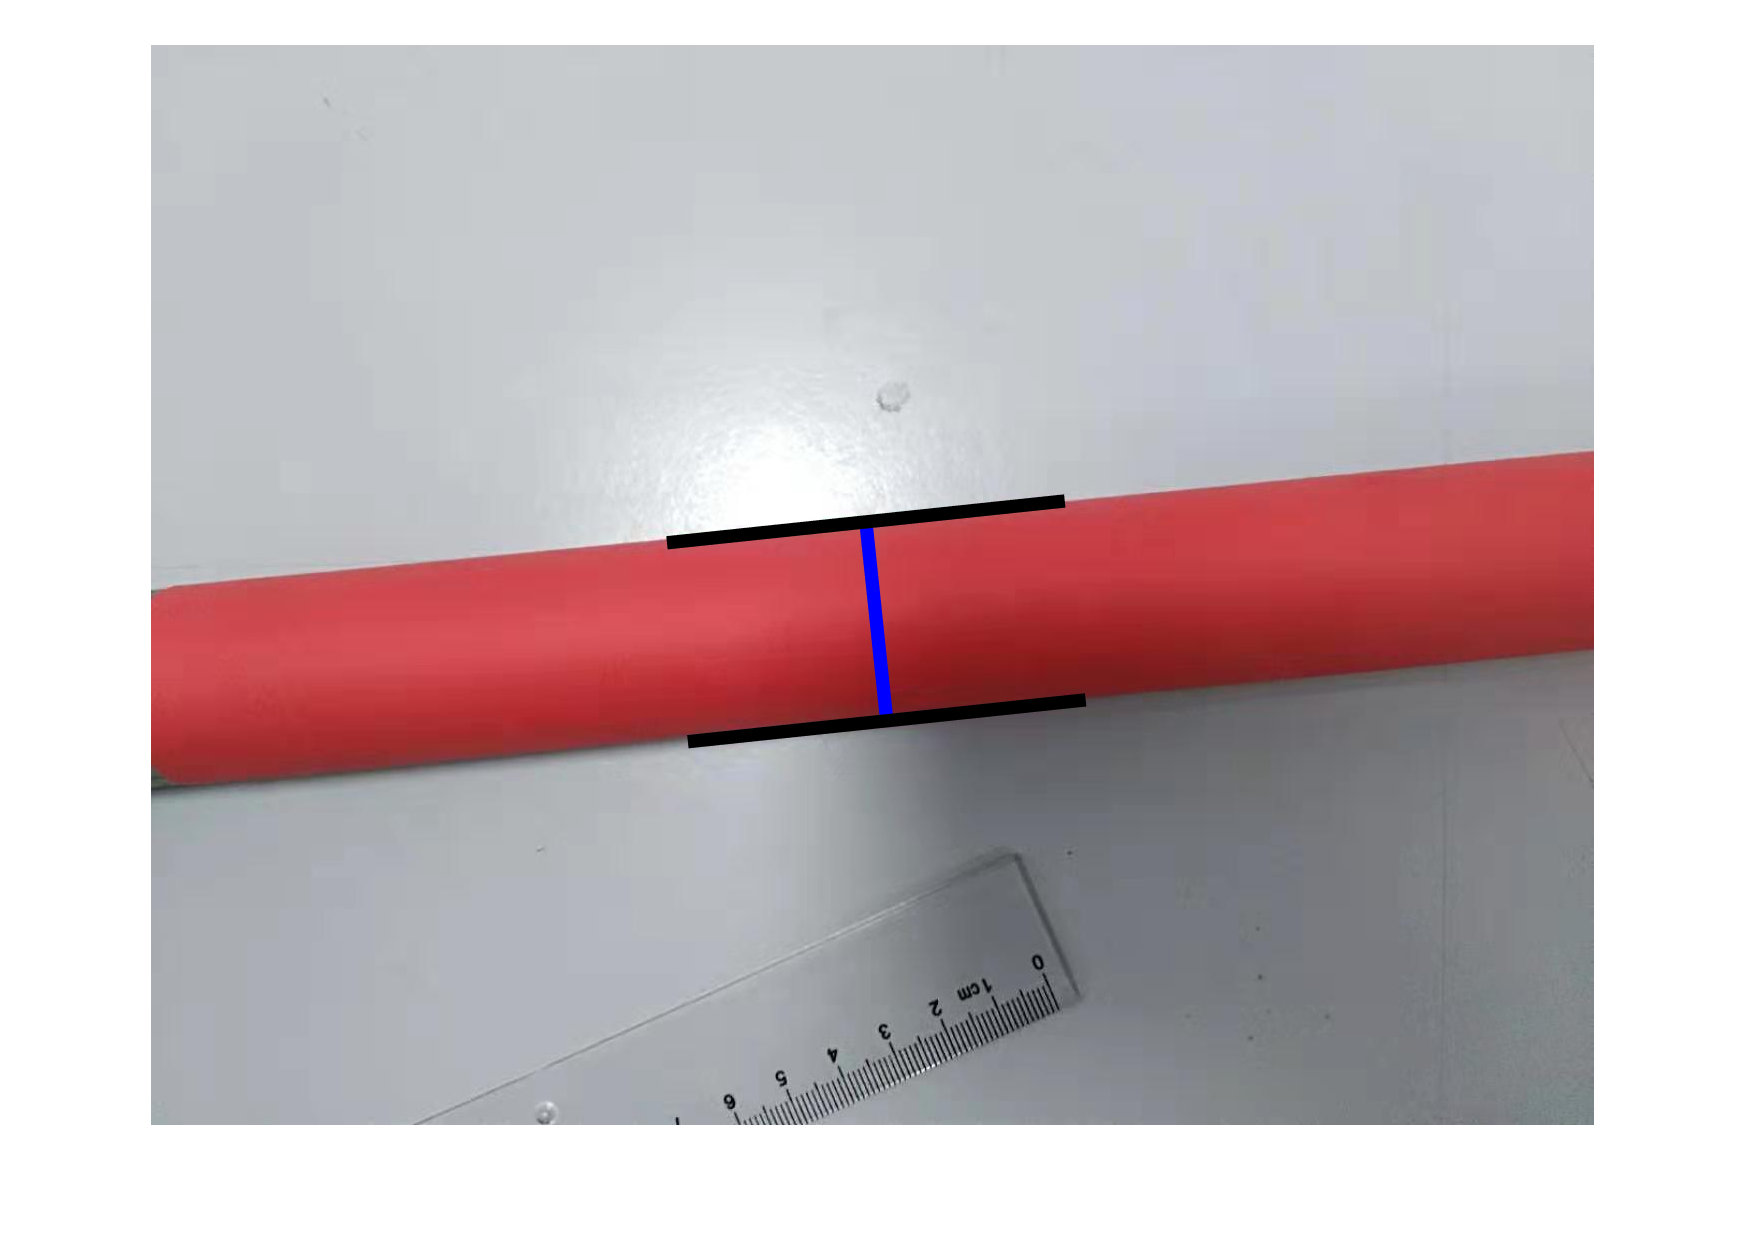

[p1, p2] = initial_points(theta1,rho1,theta2,rho2,width,height);

figure, imshow(img), hold on
plot_ruler(p1,p2);

## 3. Gradient Decent

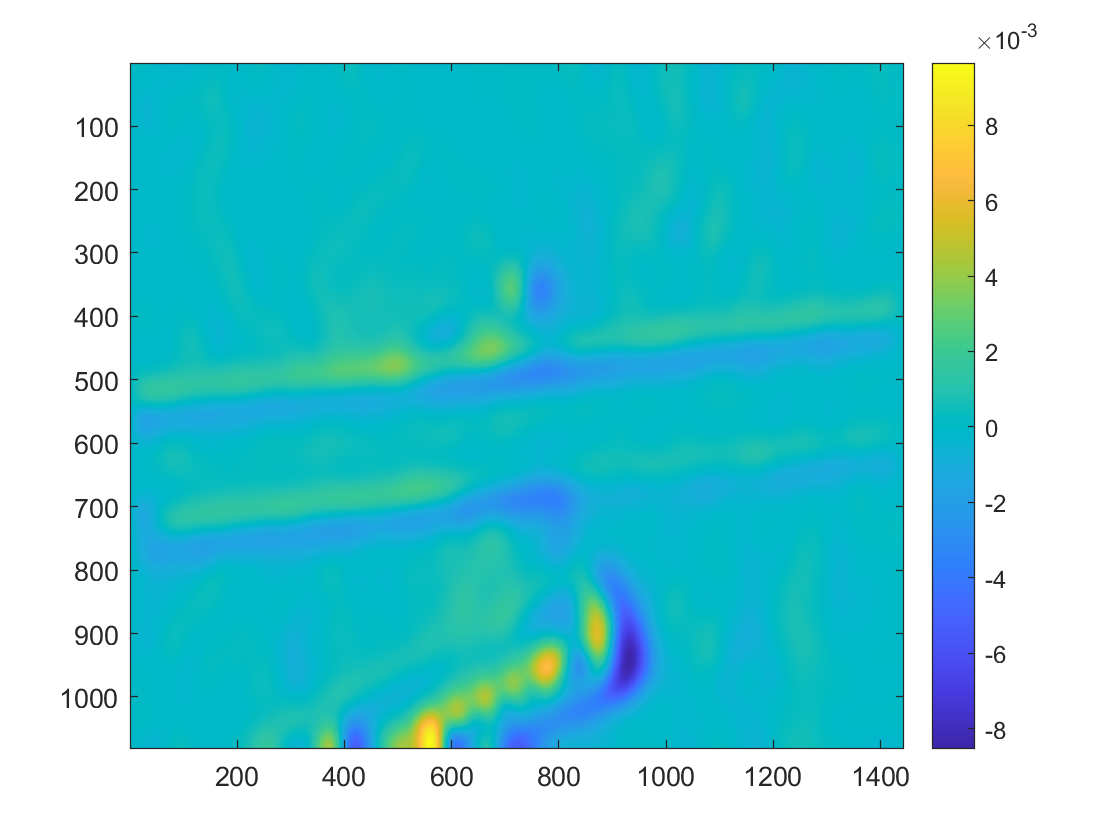

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1)), colorbar;

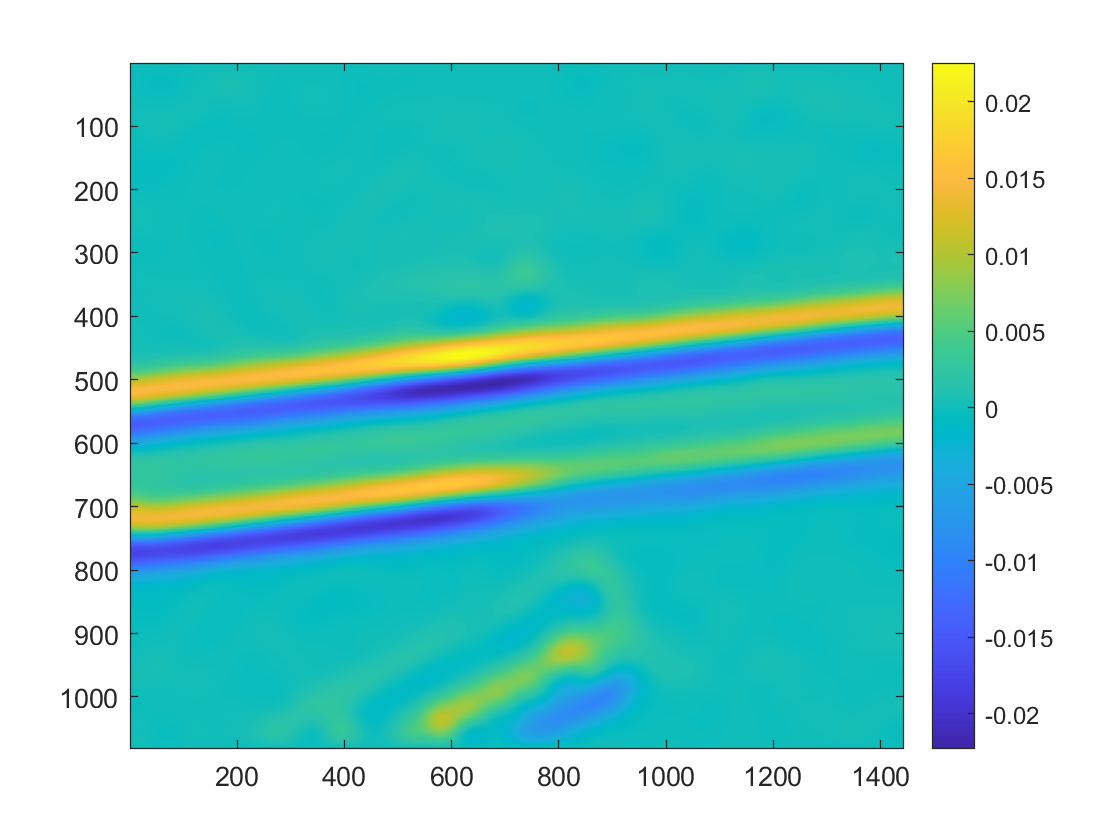

figure, imagesc(grad(:,:,2)), colorbar;

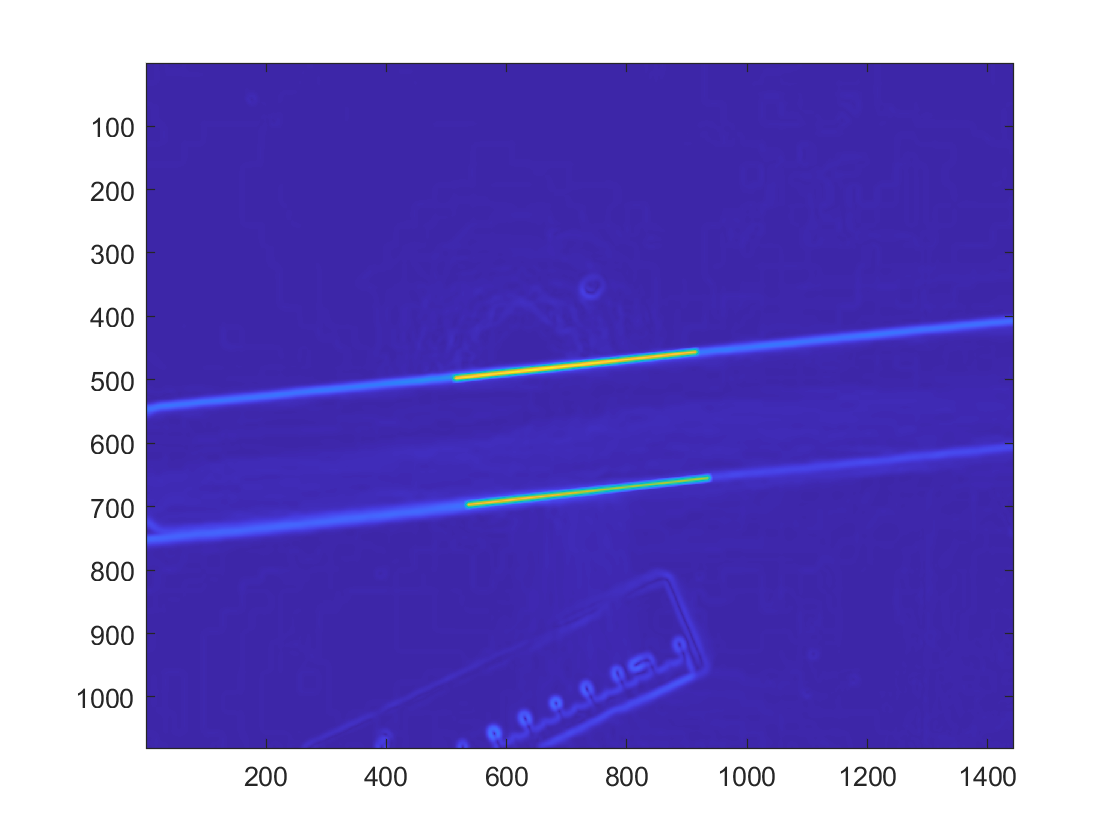

[pxs, pys] = meshgrid(1:width,1:height);
ps = zeros(0,0,0);
ps(:,:,1) = pxs;
ps(:,:,2) = pys;

[line1, line2] = lines_mask(p1,p2,ps,0,8,1);

figure, imagesc(line1+line2+edges), hold on

max_steps = 20

max_steps = 20

min_movement = 0.001

min_movement = 1.0000e-03


decent_rate = 1.0

decent_rate = 1

momentum = 1.0

momentum = 1

damping = 0.3

damping = 0.3000


thickness = 0.0

thickness = 0

expand = 8.0

expand = 8

ratio = 1.0

ratio = 1


pan_rate = 1000.0

pan_rate = 1000

rot_rate = 5.0

rot_rate = 5

spr_rate = 2.0

spr_rate = 2

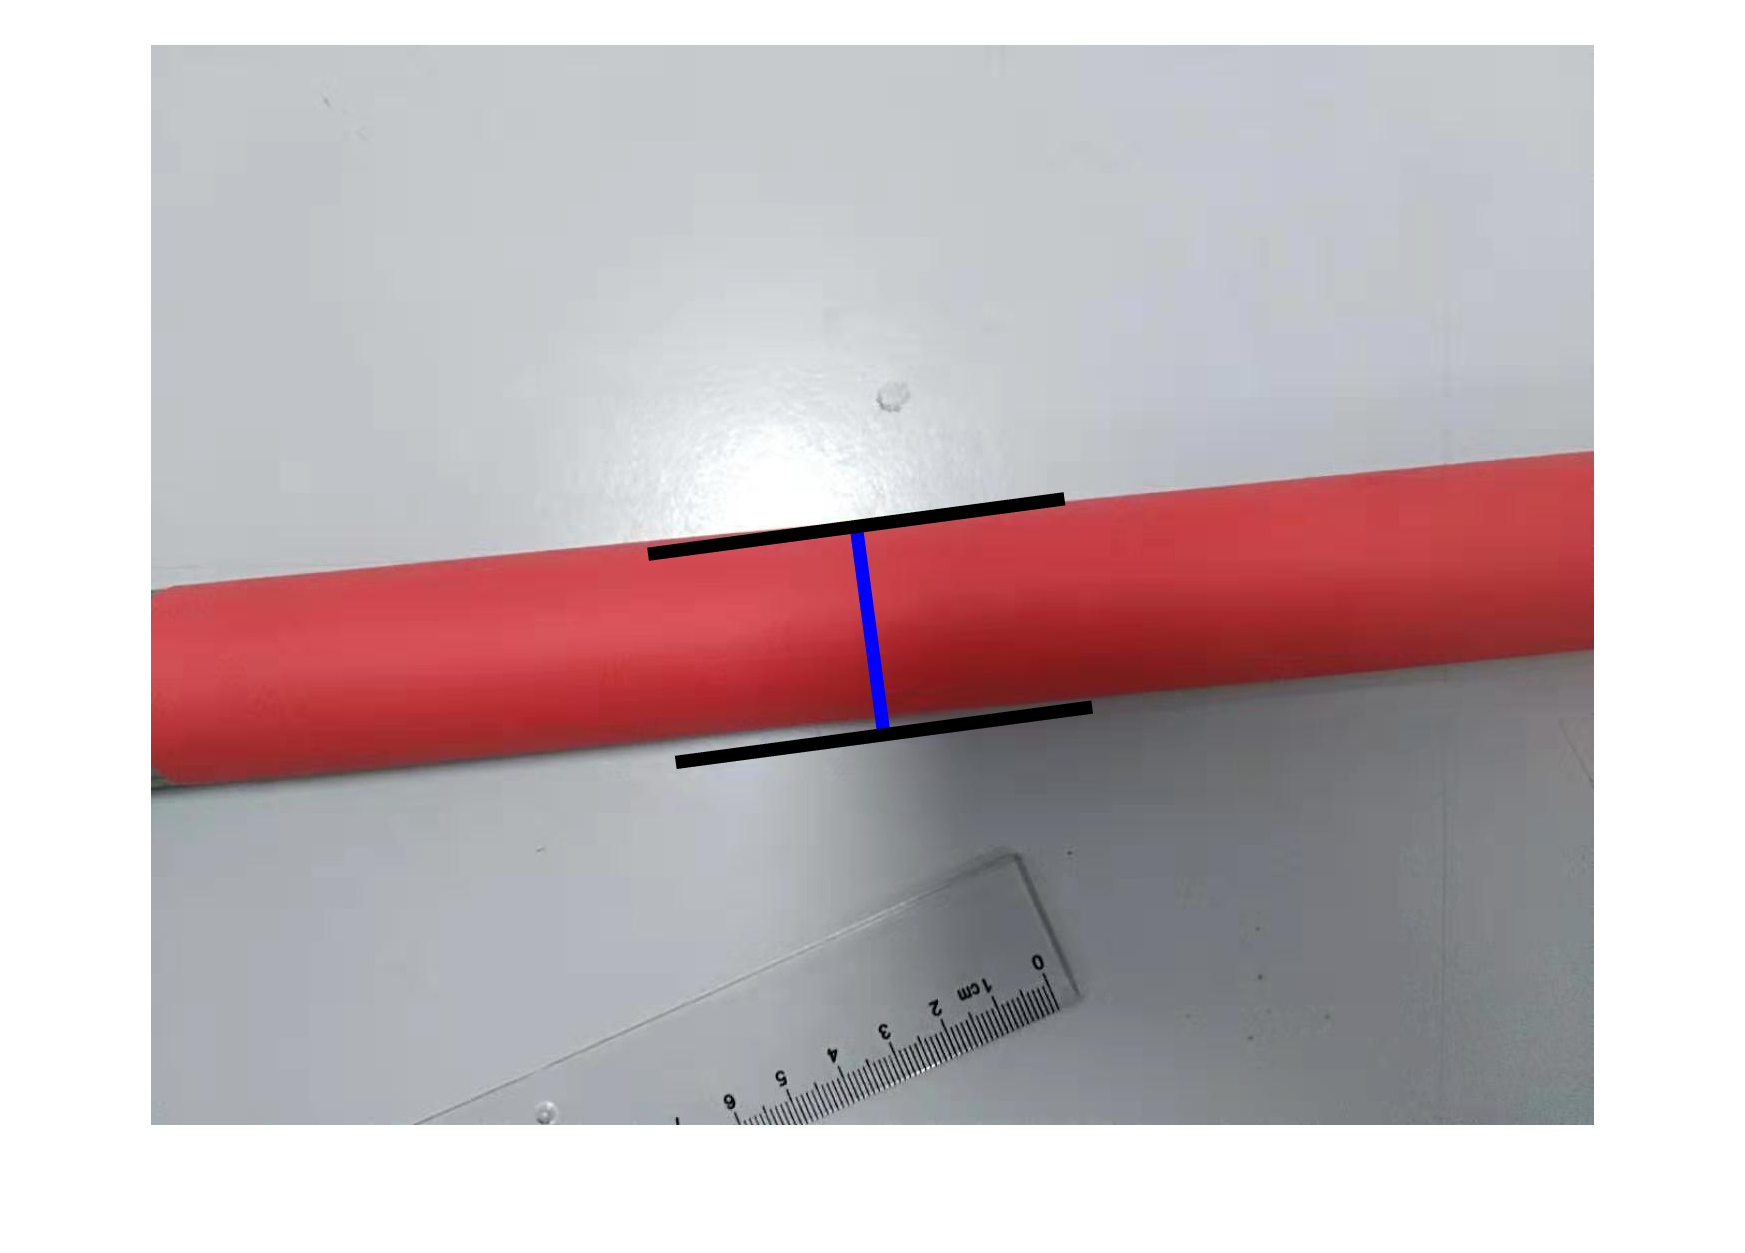

% 扰动
p1 = p1 + randn(size(p1))*(length/100);
p2 = p2 + randn(size(p2))*(length/100);

figure, imshow(img), hold on
plot_ruler(p1,p2);

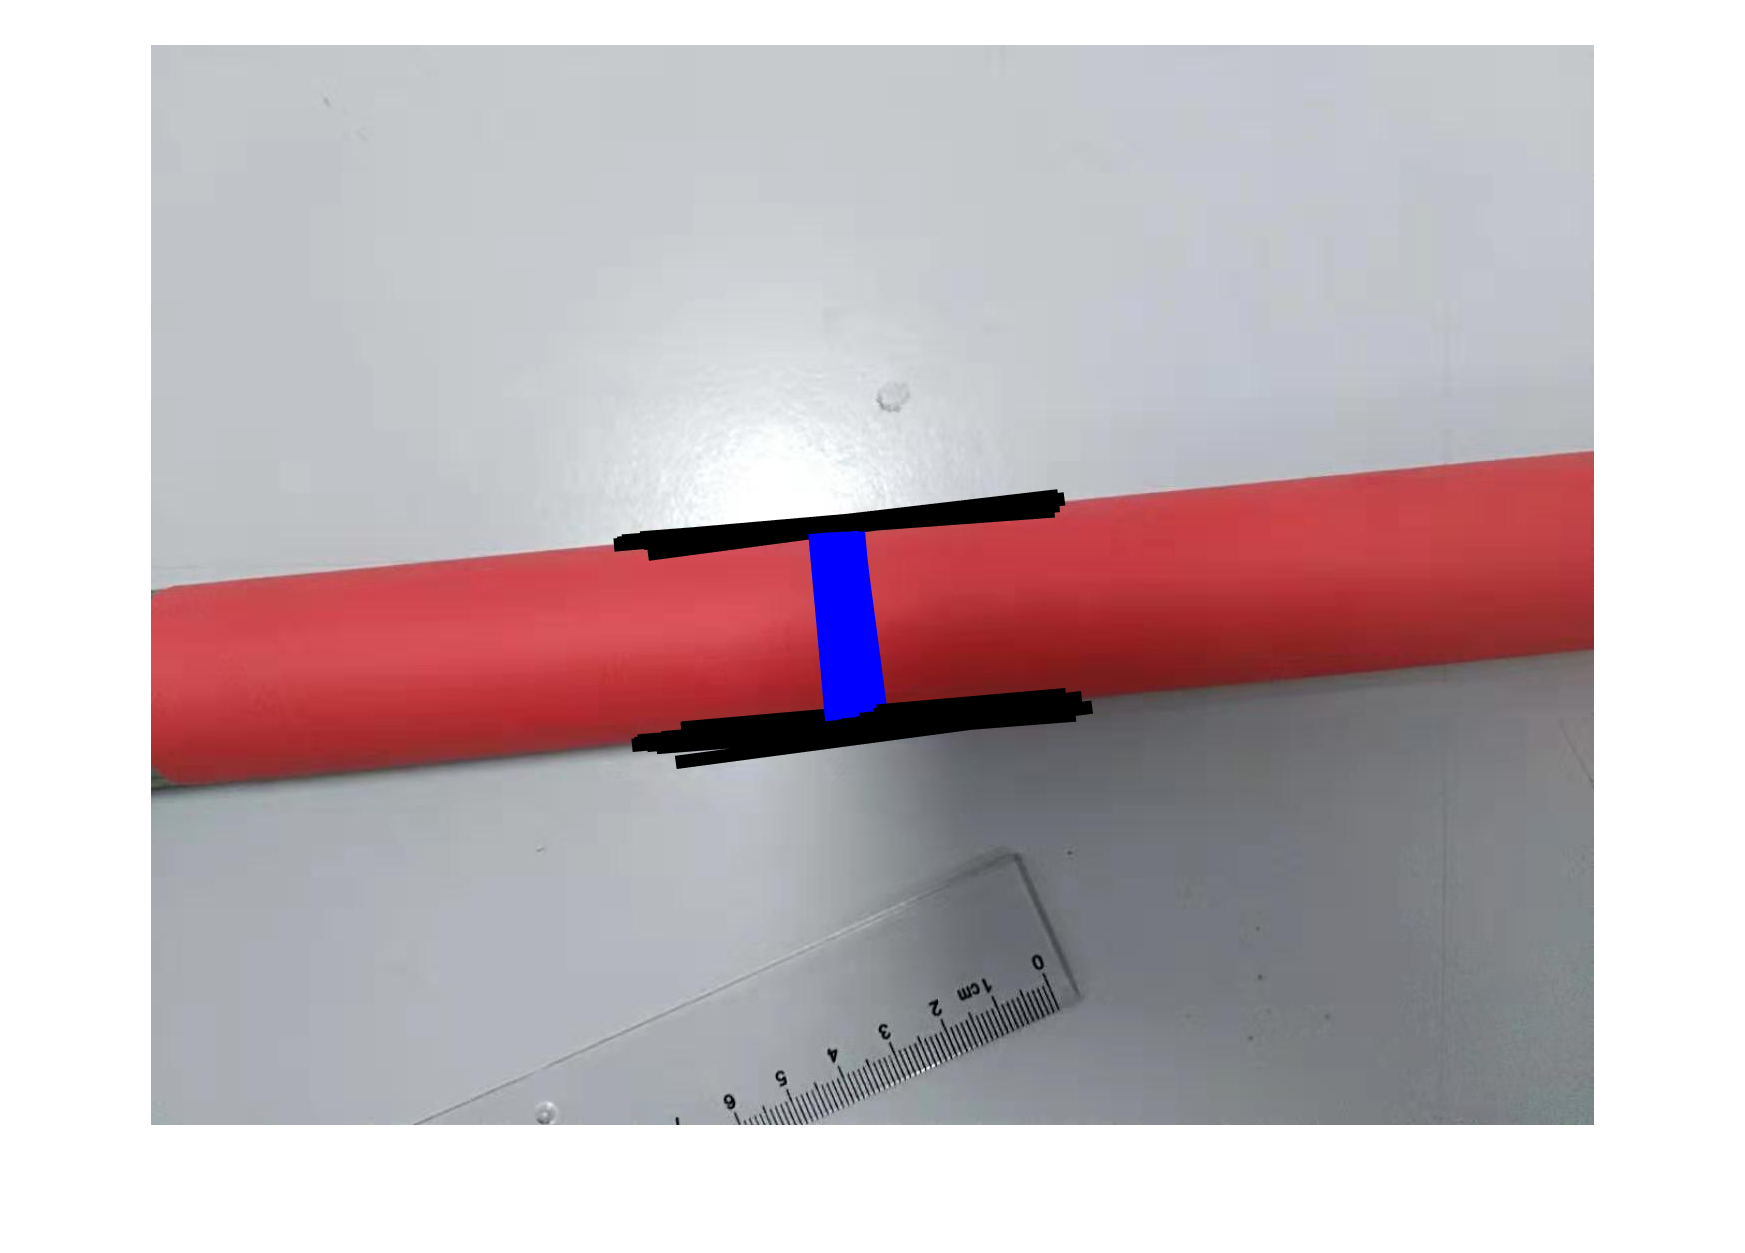

v1 = 0.0;
v2 = 0.0;

[pxs, pys] = meshgrid(1:size(grad,2),1:size(grad,1));
ps(:,:,1) = pxs;
ps(:,:,2) = pys;

D = norm(p1-p2);
L = D*ratio;

pan_m = L*(thickness+expand)/pan_rate;
rot_m = L*L*(thickness+expand)/rot_rate;
spr_m = D/spr_rate;

figure, imshow(img), hold on
plot_ruler(p1,p2);

for i=1:max_steps
    [dv1, dv2] = gradient_onestep(grad,p1,p2,ps, ...
        pan_m,rot_m,spr_m, ...
        "thickness", thickness, ...
        "expand", expand,...
        "ratio", ratio);
    
    v1 = (v1+dv1*decent_rate/momentum)*(1-damping/momentum);
    v2 = (v2+dv2*decent_rate/momentum)*(1-damping/momentum);
    p1 = p1+v1;
    p2 = p2+v2;
    
    %figure, imshow(img), hold on
    plot_ruler(p1,p2);
    
    last_D = D;
    D = norm(p1-p2);
    movement = abs(D-last_D);
    if  movement <= D * min_movement
        break;
    end
    
    L = D * ratio;
    pan_m = L*(thickness+expand)/pan_rate;
    rot_m = L*L*(thickness+expand)/rot_rate;
    spr_m = D/spr_rate;
    
end

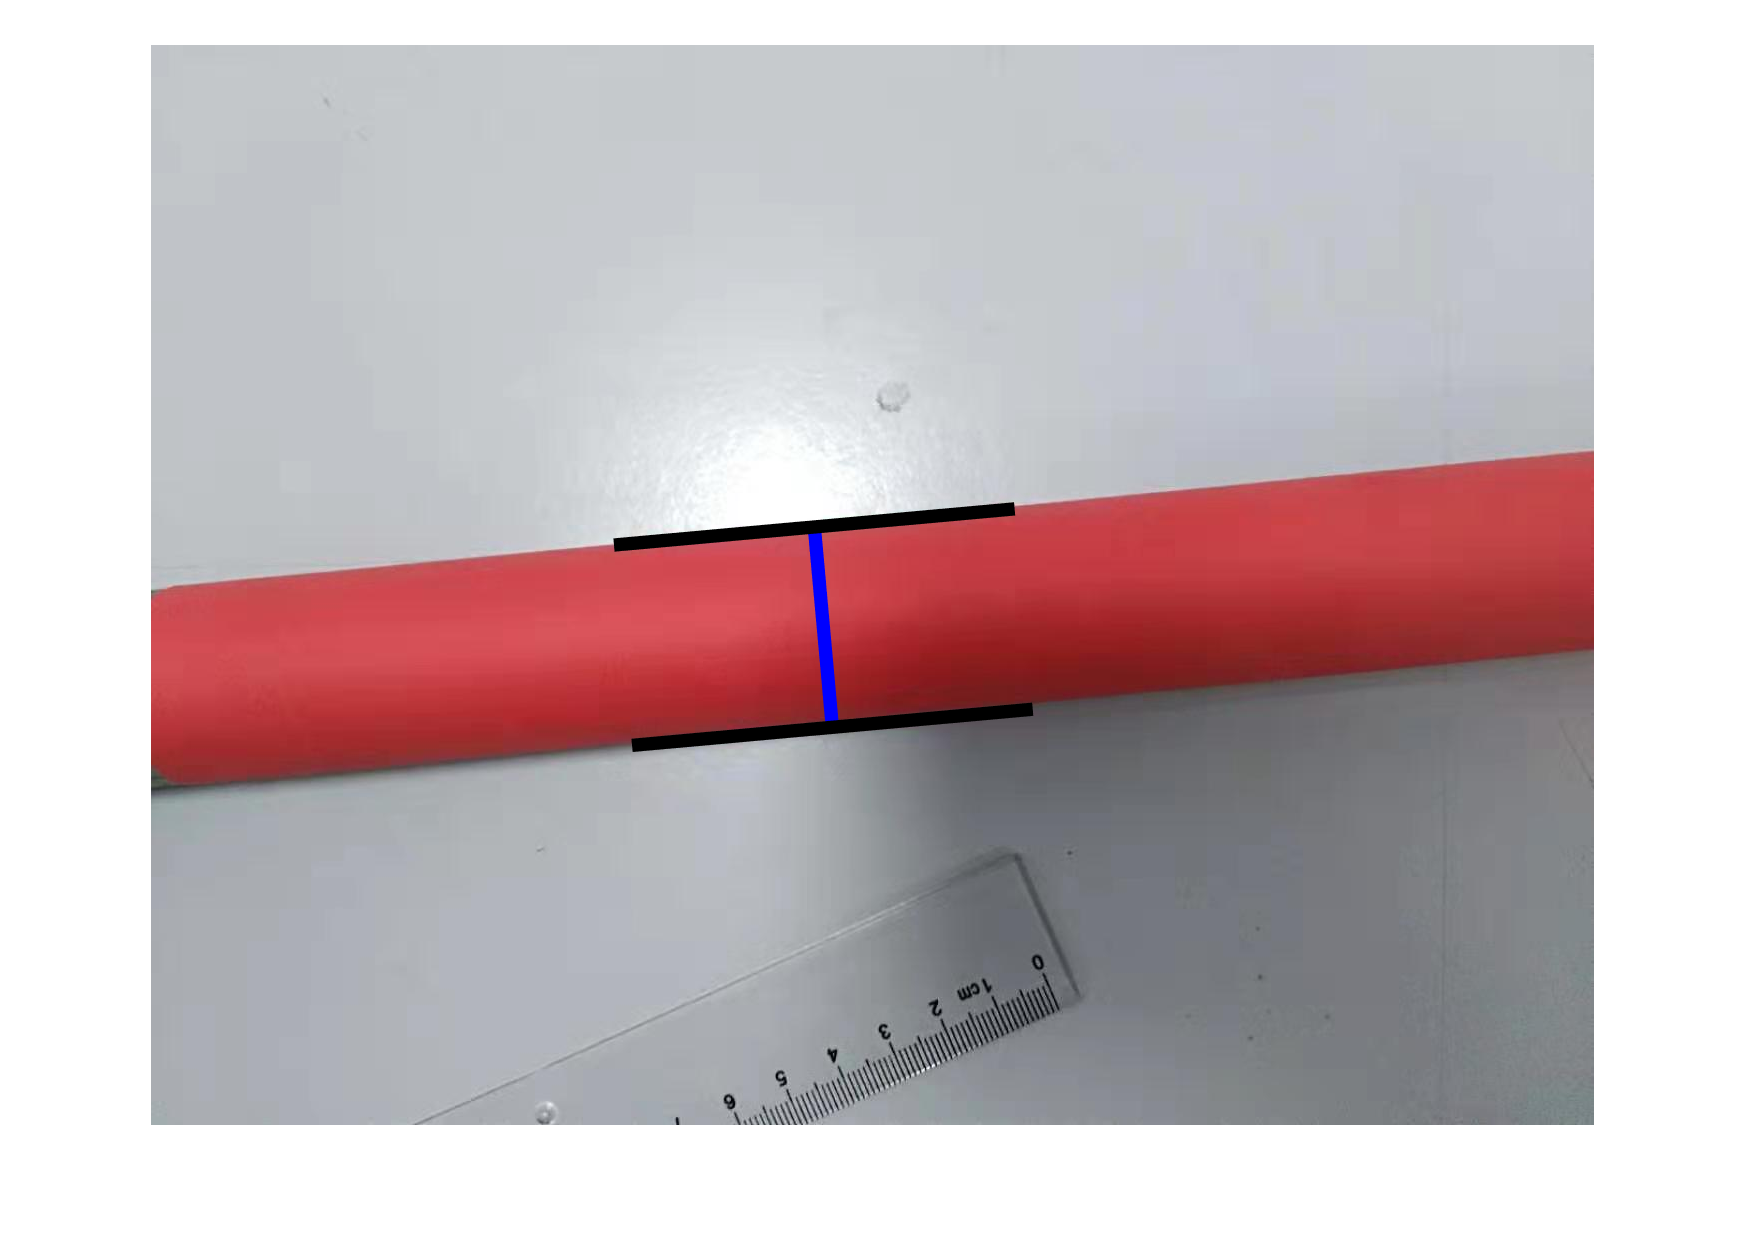


figure, imshow(img), hold on
plot_ruler(p1,p2);


steps = i

steps = 15

result = D

result = 201.1492

uncertainty = movement

uncertainty = 0.0318